## **6. gyakorlat**

#### **1. Feladat**

Legyen $f(x)=\sqrt{x}$, továbbá $x_0=1,~x_1=4,~x_2=9$ alappontok.

    a) Írjuk fel az interpolációs polinom Lagrange-alakját!

    b) Becsüljük a hibát az $x=2$  pontban és az $[1,9]$ intervallumon!

    c) Írjuk fel a Newton-alakot!

#### **2. Feladat**

Legyen $f(x)=2^x$, $x_0=0,~x_1=1,~x_2=2,~x_3=3$ alappontok.

    a) Írjuk fel az interpolációs polinom Newton-alakját!

    b) Becsüljük a hibát az  pontban!

#### **3. Feladat**

Írjuk fel azt a lineáris transzformációt, mely 

    a) a $[-1,1]$-et az $[a,b]$-re, és amely

    b) az $[a,b]$-t a $[-1,1]$-re képezi. 

#### **4. Feladat**

Igazoljuk, hogy $f \in C^2[a,b]$ esetén a lineáris interpoláció hibabecslése

$|f(x)-P_1(x)| \leq \frac{M_2}{8} (b-a)^2$,

ahol $M_2 = \|f''\|_\infty$.

### **Rajzolás kétdimenzióban**

Az `x` és `y` vektorban megadott pontokat egyenessel összekötve rajzolja ki a  `plot`  utasítás a koordináta rendszerre. A vektoroknak azonos hosszúaknak kell lenniük. A középső oszlopban megadott opciókkal pontonként is rajzolhatunk, ezt stringként kell megadni (aposztrófok között). Az első oszlopban lévő opciók a színt, a harmadikban lévőkkel a vonalak típusát adhatjuk meg, ld: [LineSpec](https://nl.mathworks.com/help/matlab/ref/plot.html#btzitot_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8).

Amikor több rajzot szeretnénk egy koordináta rendszerben elhelyezni és ezek nem vagy nehézkesen rajzolhatók ki egyetlen  `plot `utasítással, akkor a  `hold on `utasítást használjuk. Ezután minden rajz ugyanarra az ábrára kerül. (Vigyázni kell, hogy csak azonos nagyságrendű rajzok kerüljenek egy ábrába.) A `hold on `utasítást a  `hold off `oldja fel.

#### **1. Példa**

Rajzoljuk ki a következő pontokat a grafikonra, majd kössük össze őket egyenes vonallal.


$$(0,1),~
(1,-1),~
(2,6),~
(4,2),~
(3,1),~
(5,4)$$


x=[0,1,2,4,3,5];
y=[1,-1,6,2,1,4];
plot(x,y)

Figyeljük meg, hogy mivel a példában nem nagyság szerinti sorrendben adtuk meg az abszcisszákat, ezért a pontok összekötése cikk-cakkos. Ha függvényt ábrázolunk, akkor a nagyság szerinti sorrendre ügyelni kell.

#### **2. Példa**

Rajzoljuk ki a szinusz függvényt a [-4;4] intervallumon! 

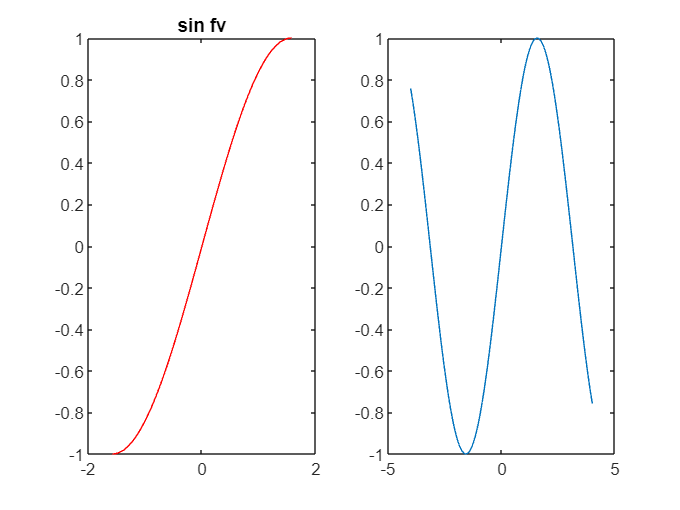

xx = linspace(-4,4,100);
yy = sin(xx);
plot(xx,yy)

### **Koordinátarendszer testreszabása**

Az  `axis `utasítással kontrollálhatjuk a koordináta rendszert. 

`axis([XMIN XMAX YMIN YMAX]):` magunk állíthatjuk be a tengelyek skálázását.

`axis auto `vagy` axis('auto'):` visszaállítja a skálázást az alapértelmezésre.

`axis equal: `a tengelyeket azonos beosztásúra állítja (kör, ellipszis, merőlegesség rajzolás esetén fontos a reális megjelenítéshez).

`axis square: `négyzet alakú rajzot készít.

A koordináta rendszerünket feldíszíthetjük különféle címkékkel:

`xlabel('x-tengely'): `az x tengelyre írt szöveg.

`ylabel('y-tengely'): `az y tengelyre írt szöveg.

`title('Összehasonlítás'):` az ábra címének megadása.

`legend('pontok','intpol'): `jelmagyarázat készítése.

A rajzunk alá rácsot is helyezhetünk:

`grid on: `rács bekapcsolása.

`grid off: `rács kikapcsolása.

### **Több rajz egy ábrán **

A `subplot `utasítással egy ábrára több rajzot is tehetünk.

`subplot(m,n,k): `egy $m$ sorból és $n$ oszlopból álló ábrát készítünk, ahol $k$ mutatja, hogy aktuálisan melyiket jelöltük ki rajzolásra (sorfolytonos számozás). Rajzolni továbbra is `plot`-tal tudunk.

`tiledlayout(m,n):` egy $m$ sorból és $n$ oszlopból álló ábrát készítünk. A következő ábrára a `nexttile `paranccsal léphetünk (a parancsot a `plot` *előtt* kell kiadni).

`tiledlayout('flow'):` akkor is használhatjuk a `tiledlayout` parancsot, ha nem tudjuk előre, hogy hány ábrát akarunk egyszerre megjeleníteni. Ilyenkor az ábrák "feltöltési sorrendjét" a MATLAB szabályozza. 

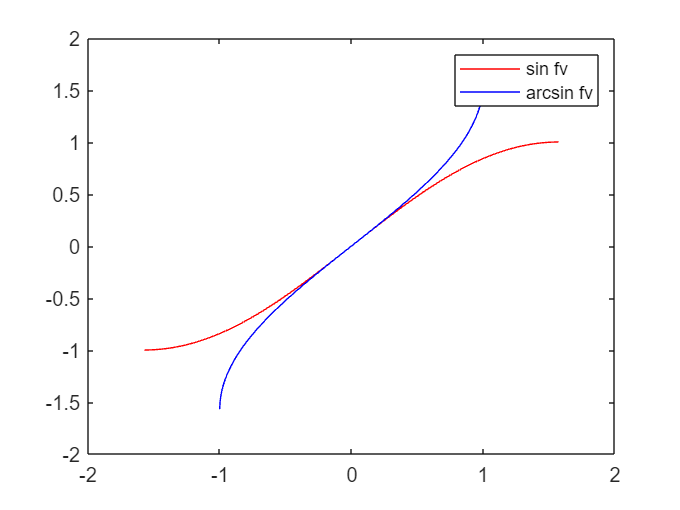

xx=linspace(-pi/2,pi/2,100);
yy=sin(xx);
subplot
plot(xx,yy,'r',yy,xx,'b')
legend('sin fv', 'arcsin fv')


% subplot(1,2,1)
% plot(xx,yy,'r')
% title('sin fv')
% subplot(1,2,2)
% plot(yy,xx,'b')
% title('arcsin fv')

### **A MATLAB interpolációs (approximációs) függvénye**

`p=polyfit(x,y,n): `

`x: `az alappontok vektora, 

`y: `a függvényértékek vektora, 

`n: `az illesztett polinom fokszáma.

Csak akkor kapunk interpolációs polinomot, ha `n==length(x)-1`. Ellenkező esetben négyzetesen közelítő polinomot kapunk, mely nem megy át a pontokon.

#### **1. Feladat**

Legyen $f(x)=\sqrt{x}$, továbbá $x_0=1,~x_1=4,~x_2=9$ alappontok.

    a) Írjuk fel az interpolációs polinom Lagrange-alakját!

    b) Becsüljük a hibát az $x=2$  pontban és az $[1,9]$ intervallumon!

    c) Írjuk fel a Newton-alakot!

#### **2. Feladat**

Legyen $f(x)=2^x$, $x_0=0,~x_1=1,~x_2=2,~x_3=3$ alappontok.

    a) Írjuk fel az interpolációs polinom Newton-alakját!

    b) Becsüljük a hibát az  pontban!

#### **5. Feladat**

Készítsük el az **1. feladatban **megadott pontokra illeszkedő másodfokú Lagrange-alappolinomokat, és jelenítsük meg őket! Címkézzük meg a rajzokat!

* Segítség: az 1. Lagrange-alappolinom kiszámítása:*

p1=poly([4,9])

p1 =      1   -13    36


p1=p1/polyval(p1,1)

p1 =     0.0417   -0.5417    1.5000


    a) Rajzoljunk egy ábrára három rajzot egymás alá a Lagrange-alappolinomokkal (ellenőrizzük a tulajdonságaikat).

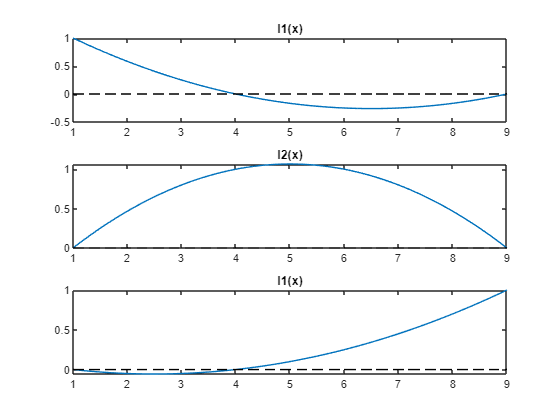

% Megoldás


    b) Rajzoljuk ki a pontokat és az azokon áthaladó interpolációs polinomot!

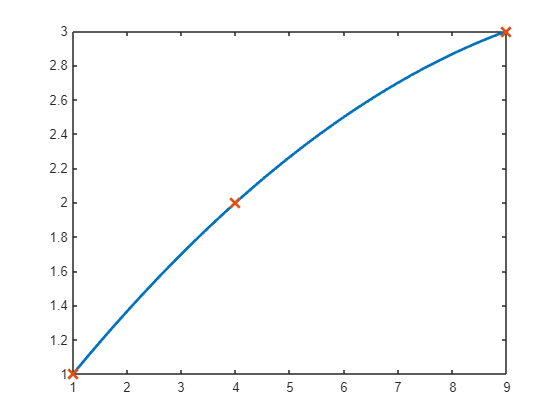

% Megoldás


    c) Rajzoljuk ki $|f(x)-L_2(x)|$-et, az interpolációs polinom hibafüggvényét! Próbáljuk leolvasni az ábráról a hibafüggvény végtelen normáját! Vessük össze az eredményt a hibabecsléssel!

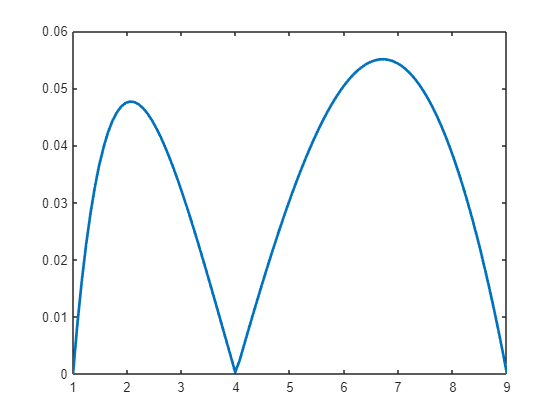

% Megoldás


**2. Feladat**

Készítsük el az $(1,1)$, $(4,2)$ és $(9,3)$ pontokra illeszkedő másodfokú interpolációs polinomot a MATLAB interpolációs függvénye használatával! Ellenőrizzük, hogy a polinom (numerikusan) megegyezik az előző feladatban meghatározott polinommal! 

% Megoldás
